# Image and Video Processing - Task 1

## Prewitt Edge Detector and Nonmaxima Suppression

Daniel Kuknyo - [Y80L35]

### Read and setup

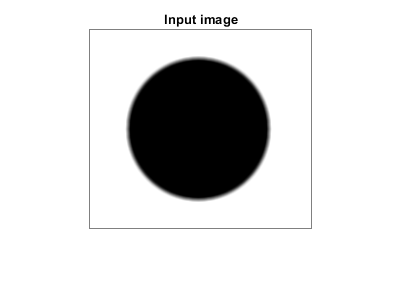

clear all; clc;

% Parameters
imname = 'circlegrey.png';
kernel_size = 2;

img = uint8(imread(imname));

figure;
imshow(img);
title('Input image');

### Setting up

% Prewitt filter mask
xmask = [-1  0  1; 
         -1  0  1; 
         -1  0  1];

ymask = [-1 -1 -1; 
          0  0  0; 
          1  1  1];

% Converting the image
img = double(im2gray(img));

M = size(img, 1);
N = size(img, 2);
G_x = zeros(M, N);
G_y = zeros(M, N);
grad_mags = zeros(M, N);

### Running the filter

We will receive the gradient magnitudes with this step

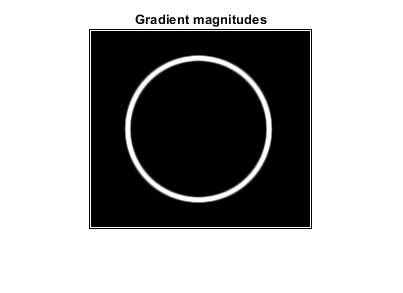

for i = 1:M - kernel_size
    for j = 1:N - kernel_size
        x = sum(sum(xmask.*img(i:i+kernel_size, j:j+kernel_size)));
        y = sum(sum(ymask.*img(i:i+kernel_size, j:j+kernel_size)));

        G_x(i+1, j+1) = x;
        G_y(i+1, j+1) = y;

        grad_mags(i+1, j+1) = sqrt(x.^2 + y.^2);
    end
end
  
grad_mags = uint8(grad_mags);

% Displaying Filtered Image
fig = figure; 
imshow(grad_mags); 
title('Gradient magnitudes');
saveas(fig, strcat('grad_mags_', imname));

### Gradient directions

grad_dirs = zeros(M, N);

for i = 1:M
    for j = 1:N
        grad_dirs(i, j) = rad2deg(atan2(G_y(i,j), G_x(i,j)));
    end
end

### Nonmaxima suppression

result = zeros(M,N);

for i = 2:M-1
    for j = 2:N-1
        if(grad_dirs(i, j) >= 0 && grad_dirs(i, j) < 22.5)
            neighbor = max(grad_dirs(i, j - 1), grad_dirs(i, j + 1));

        elseif(grad_dirs(i, j) >= 22.5 && grad_dirs(i, j) < 67.5)
            neighbor = max(grad_dirs(i - 1, j - 1), grad_dirs(i + 1, j + 1));
        
        elseif(grad_dirs(i, j) >= 67.5 && grad_dirs(i, j) < 112.5)
            neighbor = max(grad_dirs(i - 1, j), grad_dirs(i + 1, j));
        
        elseif(grad_dirs(i, j) >= 112.5 && grad_dirs(i, j) < 157.5)
            neighbor = max(grad_dirs(i - 1, j + 1), grad_dirs(i + 1, j - 1));
        
        else
            neighbor = max(grad_dirs(i, j - 1), grad_dirs(i, j + 1));
        end

        if(grad_mags(i, j) < neighbor)
            result(i, j) = 0;
        else
            result(i, j) = grad_mags(i, j);
        end
    end
end

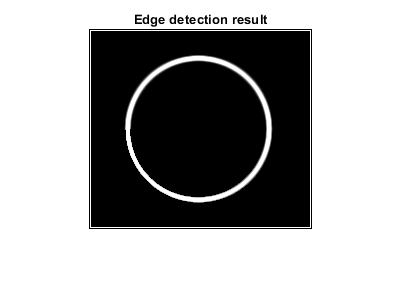

result = uint8(result);

% Displaying Output Image
fig = figure; 
imshow(result); 
title('Edge detection result');
saveas(fig, strcat('Prewitt_', imname));